# Redes Neuronales

### Tarea 2: `Dataset Breast Cancer Winsconsin (Original)`

`Realizado por:`` David Fabián Cevallos Salas`

`Fecha:`` 2023-07-13`

En esta tarea analizaremos el dataset Breast Cancer Wisconsin (Original) mediante árboles de decisión y la estrategia k-folding cross validation.

Se debe tener cargado el fichero de nombre breast-cancer-wisconsin.txt y el script MetricasBinario.m en la carpeta previo a la ejecución del live script.

El dataset se encuentra disponible en: [https://archive.ics.uci.edu/dataset/15/breast+cancer+wisconsin+original](https://archive.ics.uci.edu/dataset/15/breast+cancer+wisconsin+original)

Consta de 9 descriptores y 699 observaciones. Comprende un problema de clasificación binaria.

La solución correspondiente en Python se encuentra en: [https://colab.research.google.com/drive/1GYhFC8l4m7GvtLpAdIULtzYFD-TgK4tC#scrollTo=-9oJ9DCAk54R](https://colab.research.google.com/drive/1GYhFC8l4m7GvtLpAdIULtzYFD-TgK4tC#scrollTo=-9oJ9DCAk54R)

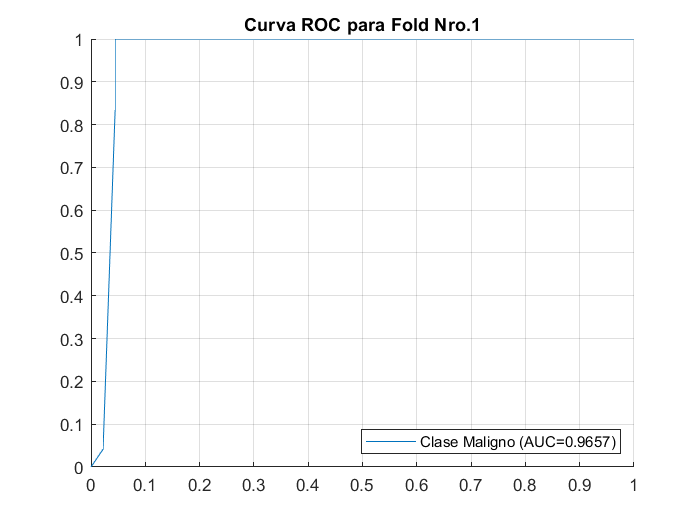

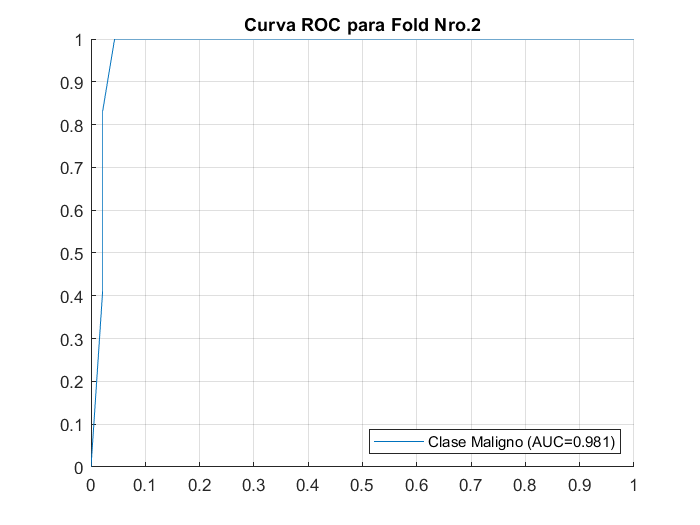

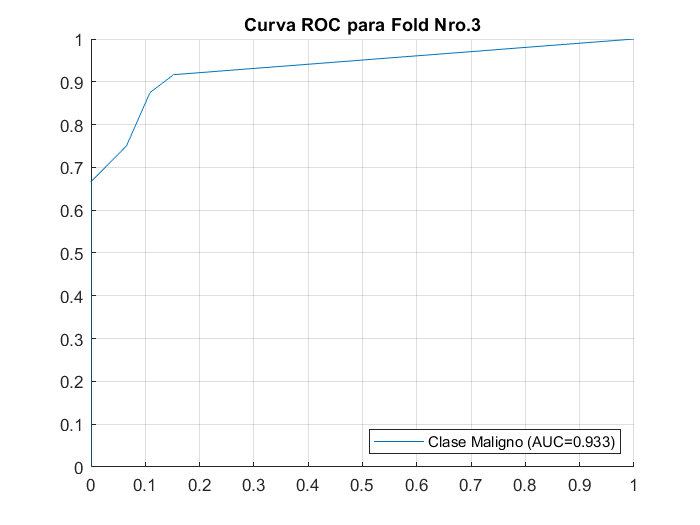

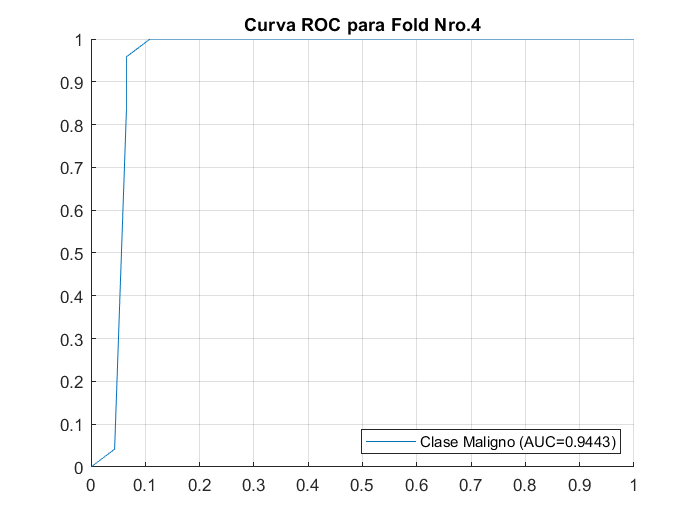

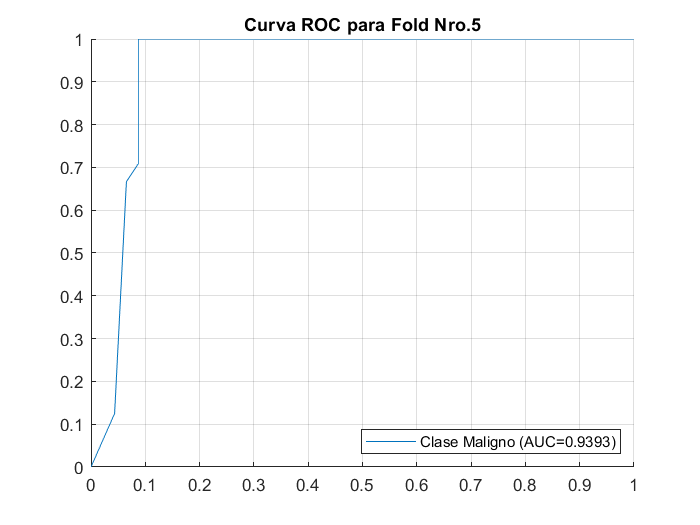

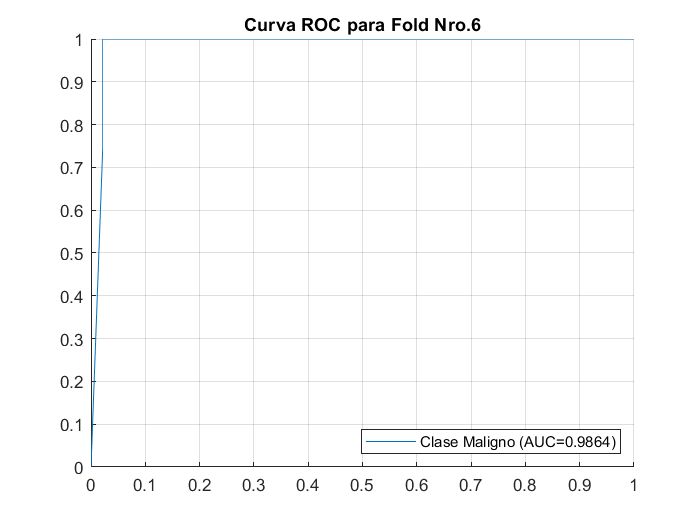

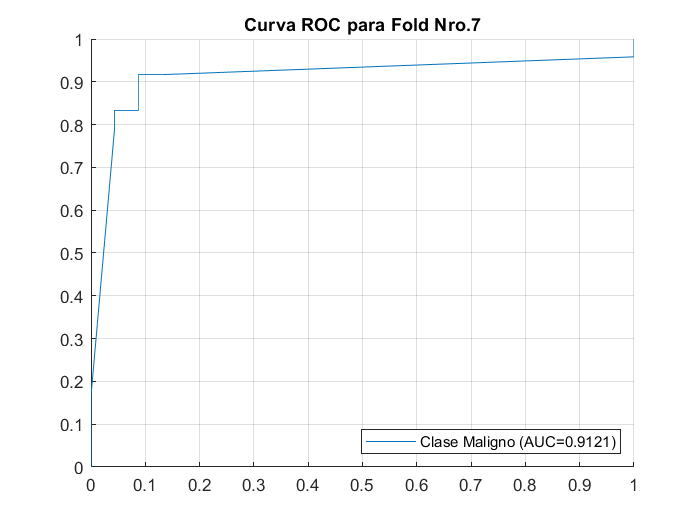

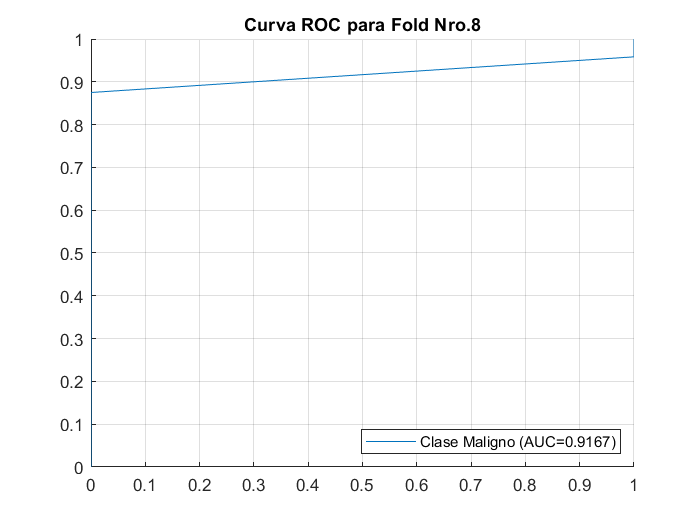

clc; 
clear;
rng(0);

% Lectura de datos
T = readtable("breast-cancer-wisconsin.txt","ReadVariableNames",false);

% Limpieza de datos
T(T.Var7=="?",7)={'1'};
T.Var7 = str2double(T.Var7);
T(T.Var11==2,11)={1};
T(T.Var11==4,11)={2};

% Establecimiento de datos finales y definición de estrategia k-Fold (10 folds)
X = table2array(T(:,2:10));
Y = table2array(T(:,11));
CVO = cvpartition(Y,"k",10);
num_pruebas = CVO.NumTestSets;
labels = [1 2];

for i = 1:num_pruebas
    % Indices de training y test
    trIdx = CVO.training(i);
    teIdx = CVO.test(i);
    % Definición de modelo Decision Tree
    ctree = fitctree(X(trIdx,:),Y(trIdx,:));
    % Predicción: etiquetas y probabilidades
    [Ypred, Yproba] = predict(ctree,X(teIdx,:));
    % Obtención de métricas (Definimos como clase positiva 
    % a la clase 2 - Maligno) 
    Met(:,i)=MetricasBinario(Y(teIdx,:), Ypred, Yproba, 2, "Maligno", i);
end


% Valores de media de métricas obtenidas
% Precision, Recall, F1-score, Accuracy, Error, AUC score
Metricas = mean(Met,2)

Metricas =     0.9021
    0.9297
    0.9128
    0.9385
    0.0615
    0.9454
